# One versus one

This question uses a subset of the iris data - only the sepal widths and sepal lengths for all three classes:

clear all;
load('multiclass.mat', 'examples', 'labels');

This question is about training and visualising a set of Support Vector Machines (SVMs) in a one versus one (OVO) configuration in order to solve a multiclass problem. You should use the whole dataset (without splitting) for training. Note that the dataset has already been z-score stadardised.

Marks are available for:

- An appropriate call to train a set of OVO SVMs on the whole dataset, with default parameters [3 marks]

- An appropriate call to train a *second* set of OVO SVMs on the whole dataset, using the kernel trick with an RBF kernel and a KernelScale of 0.4 [3 marks]

- Extending the `visualiseSVMs()` function to give a helpful visualisation of any 2D model trained by the `fitcecoc()` function (the visualisation should at least include the decision boundaries and the original training data) [8 marks]

- Using the `visualiseSVMs()` function you have developed to produce a visualisation of each of the two sets of SVMs you have trained [2 marks]

- Commenting your code to explain the steps you are taking [4 marks]

[Total: 20 marks]

ans = 150×2 table
    sepal_width    sepal_length
    ___________    ____________

       1.0156        -0.89767  
     -0.13154         -1.1392  
      0.32732         -1.3807  
     0.097889         -1.5015  
        1.245         -1.0184  
       1.9333        -0.53538  
      0.78617         -1.5015  
      0.78617         -1.0184  
     -0.36097          -1.743  
     0.097889         -1.1392  
       1.4745        -0.53538  
      0.78617           -1.26  
     -0.13154           -1.26  
     -0.13154         -1.8638  
       2.1627       -0.052331  
       3.0805        -0.17309  


ans = 150×1 categorical array
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolo

g =     1.0156   -0.8977
   -0.1315   -1.1392
    0.3273   -1.3807
    0.0979   -1.5015
    1.2450   -1.0184
    1.9333   -0.5354
    0.7862   -1.5015
    0.7862   -1.0184
   -0.3610   -1.7430
    0.0979   -1.1392


label = 150×1 categorical array
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     versicolor 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     virginica 
     virginica 
     virginica 
     versicolor 
     virginica 
     versicolor 
     virginica 
     versicolor 
     virginica 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     virginica 
     versicolor 
     versicolor 
     versicolor

score =          0   -0.5159   -0.8813
         0   -0.3333   -0.8902
         0   -0.5397   -1.0649
         0   -0.5317   -1.1049
         0   -0.6190   -0.9687
         0   -0.6619   -0.7851
         0   -0.6984   -1.1760
         0   -0.5079   -0.9213
         0   -0.5159   -1.1849
         0   -0.3889   -0.9139


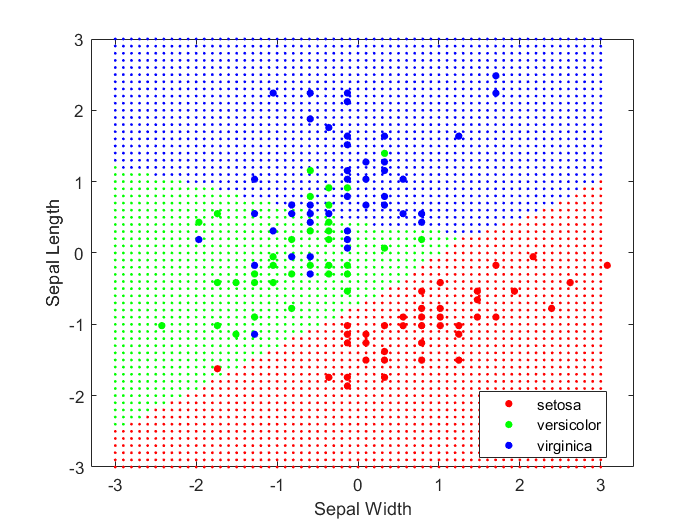

t = Fit template for classification SVM.

                     Alpha: [0×1 double]
             BoxConstraint: []
                 CacheSize: []
             CachingMethod: ''
                ClipAlphas: []
    DeltaGradientTolerance: []
                   Epsilon: []
              GapTolerance: []
              KKTTolerance: []
            IterationLimit: []
            KernelFunction: 'gaussian'
               KernelScale: 0.4000
              KernelOffset: []
     KernelPolynomialOrder: []
                  NumPrint: []
                        Nu: []
           OutlierFraction: []
          RemoveDuplicates: []
           ShrinkagePeriod: []
                    Solver: ''
           StandardizeData: []
        SaveSupportVectors: []
            VerbosityLevel: []
                   Version: 2
                    Method: 'SVM'
                      Type: 'classification'


ans = 150×2 table
    sepal_width    sepal_length
    ___________    ____________

       1.0156        -0.89767  
     -0.13154         -1.1392  
      0.32732         -1.3807  
     0.097889         -1.5015  
        1.245         -1.0184  
       1.9333        -0.53538  
      0.78617         -1.5015  
      0.78617         -1.0184  
     -0.36097          -1.743  
     0.097889         -1.1392  
       1.4745        -0.53538  
      0.78617           -1.26  
     -0.13154           -1.26  
     -0.13154         -1.8638  
       2.1627       -0.052331  
       3.0805        -0.17309  


ans = 150×1 categorical array
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolo

g =     1.0156   -0.8977
   -0.1315   -1.1392
    0.3273   -1.3807
    0.0979   -1.5015
    1.2450   -1.0184
    1.9333   -0.5354
    0.7862   -1.5015
    0.7862   -1.0184
   -0.3610   -1.7430
    0.0979   -1.1392


label = 150×1 categorical array
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     setosa 
     virginica 
     virginica 
     virginica 
     versicolor 
     virginica 
     versicolor 
     virginica 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     virginica 
     versicolor 
     versicolor 
     versicolor 
 

score =    -0.0000   -0.5097   -0.4913
         0   -0.4972   -0.5146
   -0.0000   -0.5084   -0.4916
         0   -0.5085   -0.4922
   -0.0001   -0.5088   -0.4912
   -0.0000   -0.5088   -0.4913
   -0.0000   -0.5088   -0.4912
   -0.0000   -0.5086   -0.4914
   -0.0000   -0.5088   -0.4912
         0   -0.5126   -0.5130


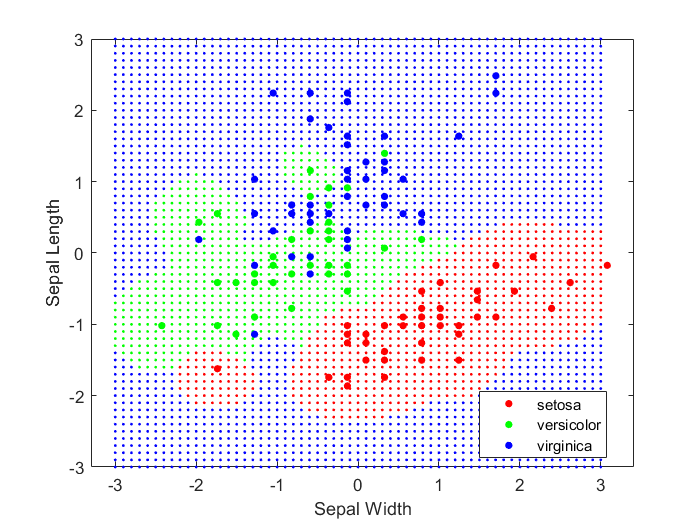

% add as many lines of code as you need below:

m = fitcecoc(examples, labels,'Coding', 'onevsone');

visualiseSVMs(m)

t = templateSVM('KernelFunction','rbf','KernelScale', 0.4)

n = fitcecoc(examples,labels,'Coding','onevsone','Learners',t);
visualiseSVMs(n)

function visualiseSVMs(m)

    % Hint: for any model, m, trained with fitcecoc(),
    % you can access the data used to train it with:
    m.X
    m.Y
    
    % Add as many lines of code as you need below:
    
    
    i = [];
    j = [];
% using a nested for loop to generate a grid of information
% -3 and 3 where selected as the min and max values as reviewing the examples table not number was higher or lower than them
% implemented intervals of 0.1 to go up in
for x = -3:0.1:3
    for y = -3:0.1:3
        
             i = [i;y];
             j = [j;x];
    end
end
% displays all of the values from the example table within a scatter graph
    i;
    j;
    q = [i, j];

    % the scatter graph was then colour coded depending on wether a value was
    % an versicolor or virginicia, the information was then displayed within a
    % group scatter graph
    [label, score] = predict(m,q);
    gscatter(i, j, label)
    
    % use hold on unitl the second graph is plotted so they over lap
    hold on
    
    % superimposing the original traing data onto the the testing data to
    % clearly show the difference in data
    % assigning two new values to equal example adn plotting them over the
    % previous graph
    
    % use m.X instead of examples
    a = m.X{:,1};  
    b = m.X{:,2};
    g = [a, b]
    [label,score] = predict(m,g)

    % use m.Y instead of labels
    gscatter(a, b, m.Y)
    
    % hold off the both graph are superimposed ontop of each other
    hold off

    xlabel('Sepal Width')
    ylabel('Sepal Length')
end